## Exercise 2.

Generate some data using `x = rand(1,50); y = x + randn(1,50);`. Split the data points in half. Fit a linear model to one half of the data (*y*= *ax*+ *b*) and compute the *R^*2 value for the goodness-of-fit. Then quantify how well this fitted model predicts the second half of the data, again summarizing performance using *R^*2. How do the two values compare? Is the answer the same for other splits of the data?

count = 50;
x = rand(1, count);
y = x + randn(1, count);

% Randomly split the data into k=2 parts
k = 2;

% All data indices, randomly ordered (vector 1*100)
ixAll = randperm(count);

% Numineach = 100/2 => 50
numineach = ceil(count / k);

% Indexes for each of the parts
ixAll = reshape([ixAll NaN(1, k * numineach - count)], k, numineach);

% Half of the dataset for traininig
xTrain = x(ixAll(1, :));
yTrain = y(ixAll(1, :));

% Half of the dataset for testing
xTest = x(ixAll(2, :));
yTest = y(ixAll(2, :));

% Fit a linear model to training data perform linear regression (OLS), 
% find weights for linear model y = a*x + b
X = [xTrain' ones(length(xTrain), 1)];
w = inv(X' * X) * X' * yTrain';

% Fitted model on the first half of data
YTrainM = X * w;
% Fitted model on the second half of data
YTestM = [xTest' ones(length(xTest), 1)] * w;

% Calculate R2 for the fitted model and actual training data
trainR2 = computeR2(yTrain, YTrainM');
% Calculate R2 for the fit model and test data
testR2 = computeR2(yTest, YTestM');

% The R2 between train part and test part is diffirent 
% because size of sample is small
% in case of a
% if n > 1000, the R2 metric for both train and test part 
% will be approximately the same (-> the model is pretty accurate)
% For n = 50 - the model is unrelaible

fprintf('R2 between the train data and fitted model: %.2f%%', trainR2);

R2 between the train data and fitted model: 41.64%

fprintf('R2 between the test data and fitted model: %.2f%%', testR2);

R2 between the test data and fitted model: -18.75%

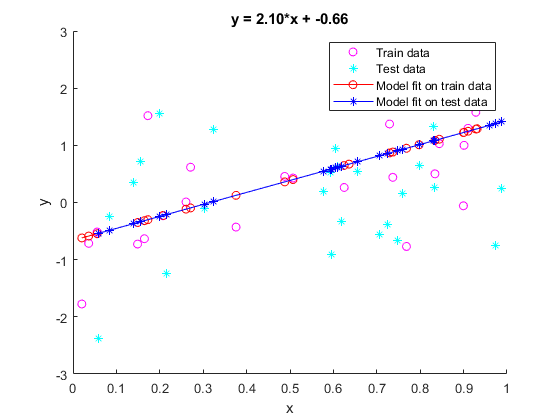

% Visualize
figure;
hold on;

a_1 = scatter(xTrain, yTrain, 'mo');
a_2 = scatter(xTest, yTest, 'c*');
b = plot(xTrain, YTrainM, 'ro-');
c = plot(xTest, YTestM, 'b*-');
xlabel('x');
ylabel('y');
legend([a_1 a_2 b c], 'Train data','Test data', 'Model fit on train data', 'Model fit on test data');
title(sprintf('y = %.2f*x + %.2f', w(1), w(2)));     

## Exercise 3. 

Generate some data using `x = rand(1, 1000); y = x + randn(1,1000);`. Let's imagine that these data constitute the complete population from which we are sampling. Draw a small sample (*n*= 10) from the population and fit a line that predicts the *y*-values from the *x*-values. Visualize this line on a figure. Repeat this for additional samples, plotting all of the lines on the same figure. How stable is the line across different samples? See what happens when you make the sample size larger (*n*= 100).

xx = rand(1, 1000);
yy = xx + randn(1, 1000);

% Perform bootstrapping 50 (repeatCount) times 
% with different size of samples 10 and 100 (sampleSize1, sampleSize2)
repeatCount = 50;

sampleSize1 = 10;
sampleSize2 = 100;

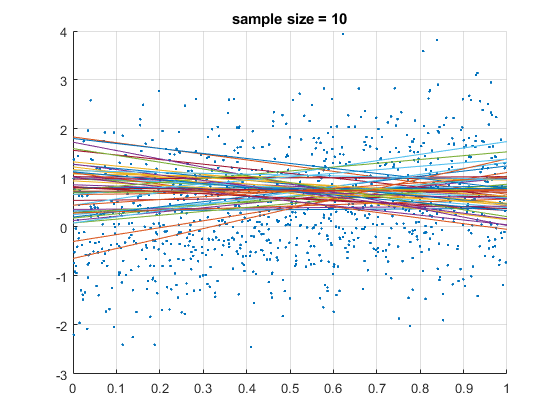

% sample size = 10
% visualise
figure;
hold on;
grid;
% add initial data
scatter(xx, yy, '.');
ax = axis;
title('sample size = 10');

% calculate matrix of indices with dimensions: [sampleSize1 x repeatCount]
% column - a vector of indices for one bootstrapped vector
indices1 = getBootstrapVectorIndices(sampleSize1, repeatCount);
xxB = xx(indices1);
yyB = yy(indices1);
% OLS
for i = 1 : repeatCount
    X = [xxB(:, i) ones(length(xxB(:, i)), 1)];
    w = inv(X' * X) * X' * yyB(:, i);

    xM = linspace(ax(1), ax(2), 100)';
    yM = [xM ones(length(xM), 1)] * w;
    plot(xM, yM);
end

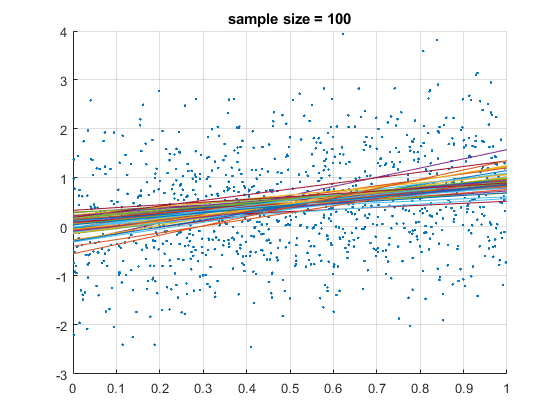

% Sample size = 100
% Visualise
figure;
hold on;
grid;
scatter(xx, yy, '.');
ax = axis;
title('Sample size = 100');

indices2 = getBootstrapVectorIndices(sampleSize2, repeatCount);
xxB = xx(indices2);
yyB = yy(indices2);
% OLS
for i = 1 : repeatCount
    X = [xxB(:, i) ones(length(xxB(:, i)), 1)];
    w = inv(X' * X) * X' * yyB(:, i);

    xM = linspace(ax(1), ax(2), 100)';
    yM = [xM ones(length(xM), 1)] * w;
    plot(xM, yM);
end

## Exercise 1. Write a function that computes coefficient of determination (*R^*2). Use the function declaration below.

%{
    function f = computeR2(model, data)

    % function f = computeR2(model, data) 

    % <model> is a 1 x N vector of model values 
    % <data> is a 1 x N vector of data points 
    %
    % returns the coefficient of determination (R^2) 
    % between <model> and <data>. This value summarizes 
    % how well <model> approximates <data>, and has 
    % an upper bound of 100%. 
%}

function f = computeR2(model, data)
    f = 100 * (1 - sum((model - data).^2) / sum((model - mean(model)).^2));
end

% Returns a two-dimension matrix with bootstrapped vector indices in columns
% samplesCount number of bootstrapped vectors 
% (result matrix: [vectorSize * samplesCount])
function indices = getBootstrapVectorIndices(vectorSize, samplesCount)   
    indices = ceil(vectorSize * rand(vectorSize, samplesCount)); 
end